# CAPÍTULO 04 - TORSIÓN

Introduce un eje y sus pares para obtener momento torsor, tensión tangencial y giro. El cálculo admite apoyos angulares y momentos distribuidos.

Dimensión: torsión alrededor del eje de una barra. Para una estructura acodada que combine torsión y flexión espacial utiliza el capítulo 7; el dibujo de una barra recta no sustituye ese análisis.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

x delimita tramos. tipoSeccion puede ser "circular", "abierta_delgada", "cerrada_delgada" o "constantes". D y di son diámetros exterior e interior. Para pared delgada, paredes contiene [longitud espesor]; areaMedia es el área encerrada por la línea media. Con "constantes", introduce J y W directamente.

x=[0 1 2.5];
G=80e9;
tipoSeccion="circular";
D=[.05 .04]; di=[0 .02];
paredes=[.10 .003; .06 .003; .10 .003; .06 .003];
areaMedia=.10*.06;
J=1e-7; W=4e-6;
pares=[1 300; 2.5 -100];
distribuidos=[];
apoyos=[0 0];

## 2. Rigidez y tensiones


$$J=\frac{\pi}{32}(D^4-d_i^4),\quad W=\frac{J}{D/2},\quad \tau_{\max}=\frac{M_t}{W},\quad \phi^\prime=\frac{M_t}{GJ}$$



$$J_{\mathrm{abierta}}\simeq\sum\frac{b_it_i^3}{3},\qquad J_{\mathrm{cerrada}}\simeq\frac{4A_m^2}{\sum b_i/t_i}$$


if tipoSeccion=="circular"
    assert(all(D>di & di>=0),'Diametros incompatibles.');
    J=pi*(D.^4-di.^4)/32; W=J./(D/2);
elseif tipoSeccion=="abierta_delgada"
    assert(all(paredes(:,1)>0 & paredes(:,2)>0),'Paredes invalidas.');
    J=sum(paredes(:,1).*paredes(:,2).^3)/3; W=J/max(paredes(:,2));
elseif tipoSeccion=="cerrada_delgada"
    assert(areaMedia>0 && all(paredes(:)>0),'Datos invalidos.');
    J=4*areaMedia^2/sum(paredes(:,1)./paredes(:,2)); W=2*areaMedia*min(paredes(:,2));
else
    assert(tipoSeccion=="constantes" && all(J>0) && all(W>0),'Tipo de seccion invalido.');
end
datos=struct('x',x,'F',J,'E',G,'puntuales',pares,'distribuidas',distribuidos,'apoyos',apoyos);
resultado=rm_axial(datos);
if isscalar(W), W=repmat(W,numel(x)-1,1); end
W=W(:); assert(numel(W)==numel(x)-1 && all(W>0),'Un W por tramo.');
xx=[]; Mt=[]; tau=[]; giro=[];
for i=1:numel(resultado.tramos)
    t=resultado.tramos(i); s=linspace(0,t.L,101)'; j=resultado.modelo.indiceOriginal(i);
    xx=[xx;t.x0+s]; Mt=[Mt;polyval(t.N,s)];
    tau=[tau;polyval(t.N,s)/W(j)]; giro=[giro;polyval(t.delta,s)];
end
disp(table(resultado.modelo.x,resultado.u*180/pi,resultado.R, ...
    'VariableNames',{'x_m','giro_grados','Reaccion_Nm'}));

    x_m    giro_grados    Reaccion_Nm
    ___    ___________    ___________

      0            0            -200 
      1      0.23344      5.6843e-14 
    2.5      -0.2225               0 



## 3. Epiuras

El signo de tau sigue al del torsor; su valor absoluto representa el máximo de la sección. En secciones cerradas aparece donde el espesor es menor. El giro se representa en grados para leerlo mejor.

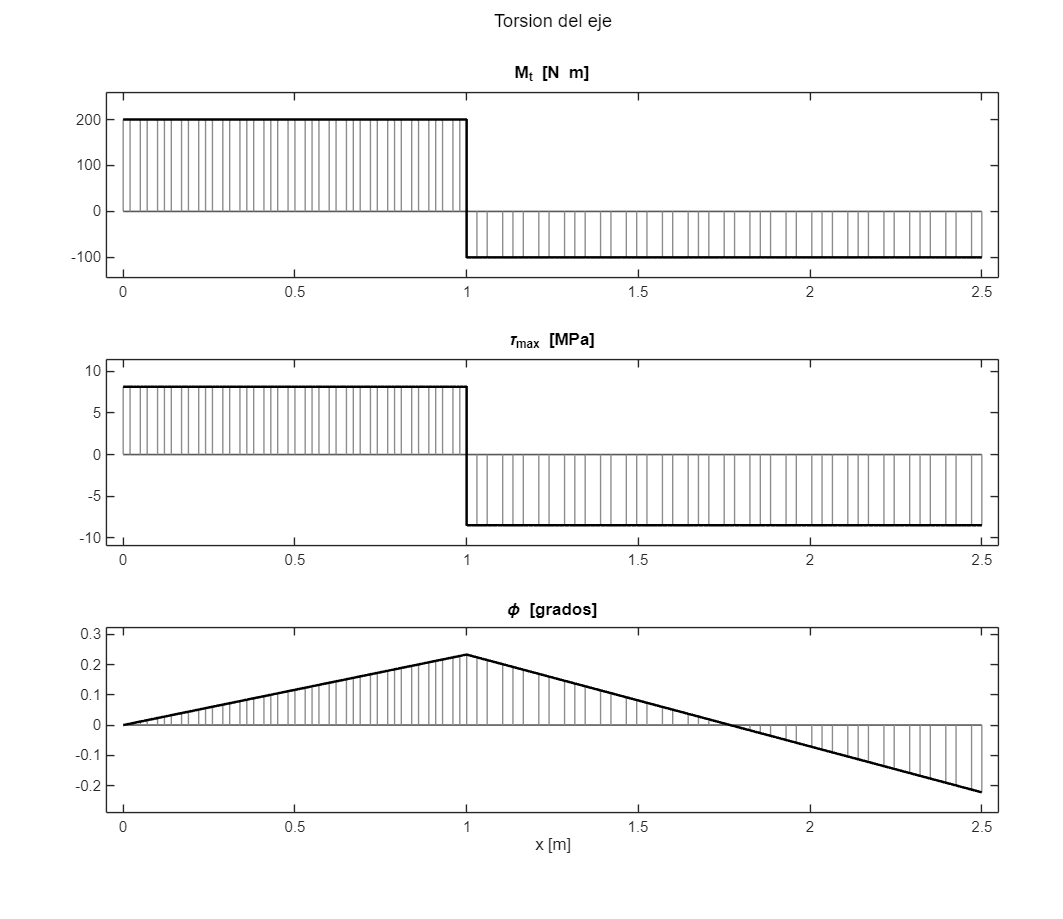

[figura,ejes]=rm_figura(3,'Torsion del eje');
rm_curva(ejes(1),xx,Mt,'M_t [N m]');
rm_curva(ejes(2),xx,tau/1e6,'\tau_{max} [MPa]');
rm_curva(ejes(3),xx,giro*180/pi,'\phi [grados]'); xlabel(ejes(3),'x [m]');

## Funciones utilizadas

rm_axial: resuelve equilibrio y compatibilidad unidimensionales. Aquí se utiliza con rigidez GJ y cargas de torsión.

polyval: evalúa un polinomio. Aquí obtiene Mt y giro dentro de cada tramo.

repmat: repite un valor o matriz. Aquí aplica un W común a todos los tramos.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Torsión de Saint-Venant con J y W constantes por tramo. Secciones circulares exactas, pared delgada abierta o cerrada de una celda mediante sus aproximaciones. Sin alabeo restringido.

Conexión con lo anterior: Reutiliza el equilibrio axial del capítulo 1 mediante la correspondencia EF con GJ y desplazamiento con giro. El momento polar del capítulo 3 solo coincide con J torsional en secciones circulares.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 04: calculo completado.');

Capitulo 04: calculo completado.
